clc;
clear;
N = 10000

N = 10000

c = 1; 
Lh = zeros(N,1);
Lv = zeros(N,1);
for i=1:1:N
    %Lv(i) = -1/c * log(rand);  %Approximativt system
    %Lh(i) = -1/c * log(rand);
    Lv(i) = rand;              %Analytisk system
    Lh(i) = 1-Lv(i);
end
maxVals = Lv + Lh;
state = ones(N,1);
pos = Lv;
clear Lv Lh ans
i = 1;
%TimeToEnd = zeros(N,1);
Bound = zeros([6000,1])

Bound =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


while(sum(state) ~= 0)
    pos = pos + ((randn(N,1))*0.01).*state; %Fiks randn til at have den rigtige størrelse af hop.
    pos = clip(pos,0,maxVals);
    state = state .* (pos ~= 0);
    state = state .* (pos ~= maxVals);
    i = i + 1;
    %TimeToEnd(state == 0 & TimeToEnd == 0) = i;
    Bound(i) = sum(state==0);
end

clear state i pos maxVals Lv Lh 

X = linspace(0,length(Bound),length(Bound))

X = 1.0e+04 *

         0    0.0001    0.0002    0.0003    0.0004    0.0005    0.0006    0.0007    0.0008    0.0009    0.0010    0.0011    0.0012    0.0013    0.0014    0.0015    0.0016    0.0017    0.0018    0.0019    0.0020    0.0021    0.0022    0.0023    0.0024    0.0025    0.0026    0.0027    0.0028    0.0029    0.0030    0.0031    0.0032    0.0033    0.0034    0.0035    0.0036    0.0037    0.0038    0.0039    0.0040    0.0041    0.0042    0.0043    0.0044    0.0045    0.0046    0.0047    0.0048    0.0049


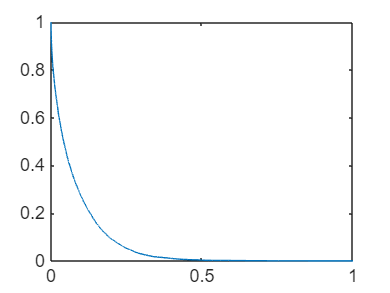

plot(X / max(X), (N - Bound)/N)


maxn = 100; %Iteration maximum for direct calculation
P_survival_direct = 0; %Set to zero before iteration
Dtc2 = linspace(0,1,1000); %Linspace DtC2
L = 1

L = 1


for n = 0:maxn-1 
    P_survival_direct = P_survival_direct + 8./((2*(n+1)-1).^2 * pi^2) .* exp(-(2*(n+1)-1).^2 * pi^2 .* Dtc2);
end %Udregnes med længdeskala for det andet system med exp fordelte længder.

P_survival_approx = exp(-4/sqrt(pi)*sqrt(Dtc2)); %approximate equation for comp.
P_survival_approx2 = P_survival_approx.^2

P_survival_approx2 =     1.0000    0.8669    0.8171    0.7809    0.7516    0.7266    0.7048    0.6854    0.6677    0.6515    0.6366    0.6227    0.6098    0.5976    0.5861    0.5752    0.5648    0.5550    0.5456    0.5366    0.5280    0.5198    0.5118    0.5042    0.4968    0.4897    0.4828    0.4762    0.4697    0.4635    0.4574    0.4515    0.4458    0.4403    0.4349    0.4296    0.4245    0.4195    0.4147    0.4099    0.4053    0.4008    0.3963    0.3920    0.3878    0.3837    0.3796    0.3757    0.3718    0.3680


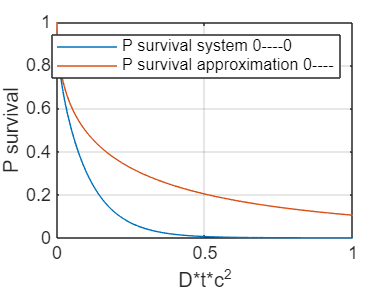

%P_survival_approx2 = (1-exp(-4/sqrt(pi)*sqrt((1/100)^2/6*Dtc2))).^2

%Plot the two equations together.
plot(Dtc2, P_survival_direct, 'DisplayName', 'P survival system 0----0');
hold on;
plot(Dtc2, P_survival_approx, 'DisplayName', 'P survival approximation 0----');
hold off; 

xlabel('D*t*c^2');
ylabel('P survival');
grid on;
legend;

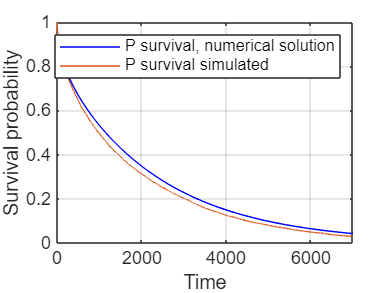

plot(Dtc2* max(X), P_survival_direct, 'DisplayName', 'P survival, numerical solution', color = "blue");

%plot(Dtc2 * max(X), P_survival_approx, 'DisplayName', 'P survival, approximation single target', color = "red");
%plot(Dtc2 * max(X), P_survival_approx2, 'DisplayName','P survival, approximation');
hold on;
plot(X, (N - Bound)/N, 'DisplayName', 'P survival simulated')
hold off; 

xlim([0,7000])
xlabel('Time');
ylabel('Survival probability');
legend;
grid on;